filename = 'data.txt';
formatSpec = '%f %f %d';
fileID = fopen('data.txt', 'r');
data = fscanf(fileID, formatSpec, [3 Inf]);
data = data';
fclose(fileID);

x_train = data(:,1:2);
y_train = data(:,3);
shape = size(x_train);
n = shape(1);
p = shape(2);

Iteration 1:
eta: 36.098667
Log barrier obj:-1467328.386326
Obj:-30.797144
Iteration 2:
eta: 34.814889
Log barrier obj:-1541453.481774
Obj:-31.197149
Iteration 3:
eta: 34.222424
Log barrier obj:-1577406.594101
Obj:-31.379167
Iteration 4:
eta: 33.636910
Log barrier obj:-1614175.015538
Obj:-31.558893
Iteration 5:
eta: 32.470669
Log barrier obj:-1691381.553406
Obj:-31.917238
Iteration 6:
eta: 30.109842
Log barrier obj:-1866085.700816
Obj:-32.644516
Iteration 7:
eta: 27.403435
Log barrier obj:-2104632.636696
Obj:-33.497901
Iteration 8:
eta: 26.010068
Log barrier obj:-2247792.749102
Obj:-33.952166
Iteration 9:
eta: 23.268289
Log barrier obj:-2578703.717592
Obj:-34.834598
Iteration 10:
eta: 20.762947
Log barrier obj:-2958213.228121
Obj:-35.649567
Iteration 11:
eta: 18.436358
Log barrier obj:-3403564.066185
Obj:-36.412265
Iteration 12:
eta: 17.417382
Log barrier obj:-3636650.424913
Obj:-36.752057
Iteration 13:
eta: 16.909621
Log barrier obj:-3763337.040998
Obj:-36.921888
Iteration 14:
eta: 16

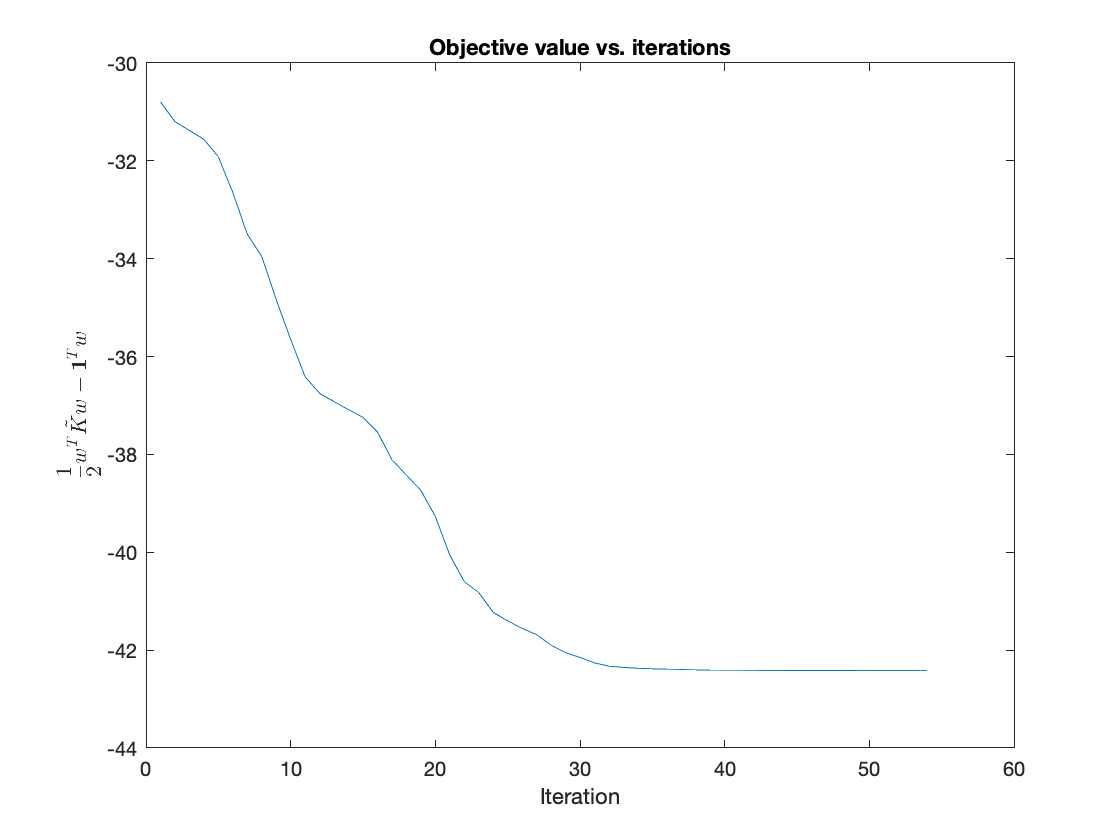

C = 0.1;
gamma = 500;
mu = 1000;
alpha = 0.01;
step_beta = 0.5;
epsilon = 1e-6;
[w, beta, beta_0, obj] = train_svm_barrier(x_train,y_train,...
    gamma,C,mu,alpha,step_beta,epsilon);

fprintf("Objective value at w*: %f\n", obj);

Objective value at w*: -42.417465


fprintf("Number of support vectors: %d\n", ...
    find_sv_num(w));

Number of support vectors: 745


[error, error_ps, error_ng]=classification_error(x_train, y_train, ...
    gamma, C, w, beta, beta_0);
fprintf(['gamma=%d, C=%.2f, classification error: %.4f;' ...
    ' False positive: %.4f; False negative: %.4f\n'], ...
    gamma, C, error, error_ps, error_ng);

gamma=500, C=0.10, classification error: 0.0012; False positive: 0.0026; False negative: 0.0000
